# Wave Equation - PDE (Finite difference method)

Derives the equations of motion for a (nonuniform) lumped parameter cantilever made up of multiple sections. We may taper the beam by changing the height of each section.

% Options
sympref('AbbreviateOutput', false);
N = 10; % number of states when finite differencing

% Parameters of wave equation
params = struct;
vecs = struct;   % for vector parameters
params.c = 1;           % speed

% initial condition - NB: should be vector of size N:
vecs.h = zeros(N, 1);
vecs.h(floor(N/2)) = 1;
vecs.dh = zeros(N, 1);
vecs.y0 = [vecs.h; vecs.dh];
vecs.y0 = vecs.y0(:);

% Parameters
syms c;

% coordinates
syms x;
syms t;

% symfuns
syms y(x,t);

## Model building, to get equations of motion

First build the PDE, then create a finite difference approximation

% Wave equation with speed 'c', no dispersion
PDE = diff(diff(y, t), t) == c^2 * diff(diff(y, x), x)

$$PDE(x, t) = \frac{\partial^{2}}{\partial t^{2}}y\left(x,t\right)=c^{2}\,\frac{\partial^{2}}{\partial x^{2}}y\left(x,t\right)$$

% Create finite difference approximations for the 'x' variation (not 't')
syms Y(t) [N 1]

% Define linear operators (matrices) for derivatives using central differences
D = diag(ones(N-1,1),1) - diag(ones(N-1,1),-1);  % First derivative 
D2 = diag(ones(N-1,1),1) -2*diag(ones(N,1)) + diag(ones(N-1,1),-1); % Second derivative

% Construct finite difference approximation (ODE)
ODE = subs(PDE, {diff(diff(y, t), t), diff(diff(y, x), x), diff(y,t), diff(y, x), y}, ...
    {diff(diff(Y,t),t), D2*Y, diff(Y,t), D*Y,  Y,})

$$ODE(x, t) = \left(\begin{array}{c} \frac{\partial^{2}}{\partial t^{2}}Y_{1}\left(t\right)=-c^{2}\,\left(2\,Y_{1}\left(t\right)-Y_{2}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{2}\left(t\right)=c^{2}\,\left(Y_{1}\left(t\right)-2\,Y_{2}\left(t\right)+Y_{3}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{3}\left(t\right)=c^{2}\,\left(Y_{2}\left(t\right)-2\,Y_{3}\left(t\right)+Y_{4}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{4}\left(t\right)=c^{2}\,\left(Y_{3}\left(t\right)-2\,Y_{4}\left(t\right)+Y_{5}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{5}\left(t\right)=c^{2}\,\left(Y_{4}\left(t\right)-2\,Y_{5}\left(t\right)+Y_{6}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{6}\left(t\right)=c^{2}\,\left(Y_{5}\left(t\right)-2\,Y_{6}\left(t\right)+Y_{7}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{7}\left(t\right)=c^{2}\,\left(Y_{6}\left(t\right)-2\,Y_{7}\left(t\right)+Y_{8}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{8}\left(t\right)=c^{2}\,\left(Y_{7}\left(t\right)-2\,Y_{8}\left(t\right)+Y_{9}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{9}\left(t\right)=c^{2}\,\left(Y_{8}\left(t\right)-2\,Y_{9}\left(t\right)+Y_{10}\left(t\right)\right)\\ \frac{\partial^{2}}{\partial t^{2}}Y_{10}\left(t\right)=c^{2}\,\left(Y_{9}\left(t\right)-2\,Y_{10}\left(t\right)\right) \end{array}\right)$$

## Numerical solution of equations of motion

We can also find numerical solutions to the EOM by using Matlab's IVP solvers like ode45. We must first convert the equations to first order:

% Numerical solution using ode45
Yf = formula(Y);
% [SSeq,S] = stateSpaceEquations(ODE,{Y1,Y2,Y3,Y4,Y5,Y6,Y7,Y8,Y9,Y10});

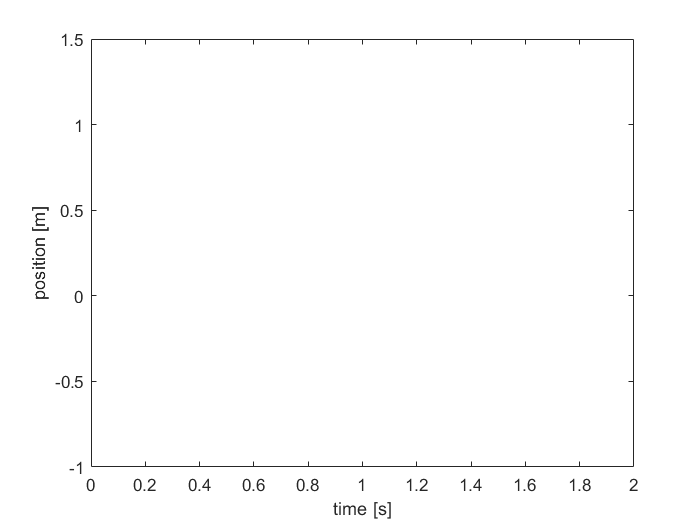


% Code generate a function to evaluate the RHS of these first order ODEs
F = subs(SSeq, params);
f = matlabFunction(F,'vars',{t,S});

% Numerical solution using ode45
opts = odeset('RelTol', 1e-6);
odesol = ode45(f, [0,10], vecs.y0, opts);

tt = odesol.x;
yy = odesol.y(1:2:end);
vv = odesol.y(2:2:end);

% Visualise motion of system 
for k=1:length(tt)
    plot(tt, yy(:,k));
    xlabel('time [s]'); ylabel('position [m]');
    drawnow;
    frm(k) = getframe(gcf);
end

fig = figure;
movie(fig,frm,1);    

## Get mass and stiffness matrices for the system

In this part, we express the equations of motion in the (linearised) second order matrix form $M\ddot{x}+C\dot{x}+Kx=G$

% % We will linearise around the equilibrium point
% x_lin = eq_point;
% v_lin = zeros(N,1);
% 
% % M is Jacobian w.r.t. the accelerations, evaluated at equilibrium point
% M = -jacobian(eom_vars, a);
% M = subs(M, [x,v], [x_lin, v_lin])
% % C is Jacobian w.r.t. velocities, evaluated at linearisation point
% C = -jacobian(eom_vars, v);
% C = subs(C, [x,v], [x_lin, v_lin])
% % K is the Jacobian w.r.t. positions, at linearisation point
% K = -jacobian(eom_vars, x);
% K = subs(K, [x,v], [x_lin, v_lin])
% % Weight vector G is the constants, but the easiest way to get them is:
% G = simplify(diff(eom_vars,g))*g

## Code Generate a simulink model to simulate the (linearised) system

% % Form the right-hand side of the linearised (really, affine due to G!) system ODEs in state-space form
% ode_rhs = [M_uf \ (G_uf - C_uf*v - K_uf*x);  v];
% S = [v; x];
% IC = strcat('zeros(', num2str(2*N) ,',1)');      % zero initial conditions 
% 
% % Generate simulink model
% openLoopModel(ode_rhs, S, [], IC, 'cantilever');